close all
clear variables

starNames= importdata('star_names.csv')';
lambdaStart=importdata('lambda_start.csv');
lambdaDelta=importdata('lambda_delta.csv');
spectra = importdata('spectra.csv');

lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/c


nombers = size(spectra,1);
nomberOfStars = size(spectra,2);
lambdaEnd = lambdaStart + (nombers-1)*lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

[Ha,ind] = min(spectra);
lambdaHa = lambda(ind)';

z = (lambdaHa/lambdaPr)-1;
speed = z * speedOfLight;
movaway=starNames(speed>0)

movaway = 1×3 cell array
    {'HD5211'}    {'HD56030'}    {'HD94028'}





fg1 = figure

fg1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [681 679 560 420]
       Units: 'pixels'

  Show all properties


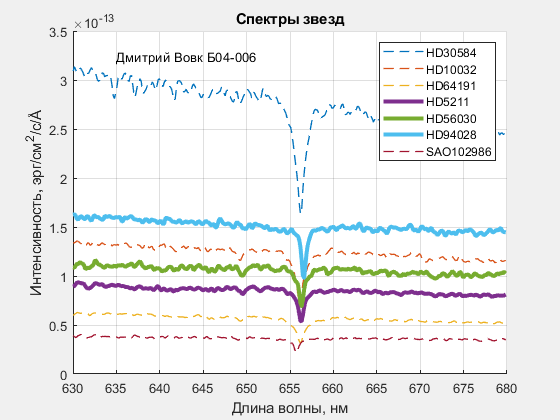


set(fg1, 'Visible' , 'on');
xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/с/',char(197)])
title('Спектры звезд')
grid on
hold on
for i=1:1:nomberOfStars
    if speed(i)>0
        plot(lambda,spectra(:,i),'LineWidth',3)
    else
        plot(lambda,spectra(:,i),'--','LineWidth',1)
    end
end
legend(starNames)
text(635,spectra(1,1)*1.05,'')
hold off
saveas(fg1,'spectra.png')